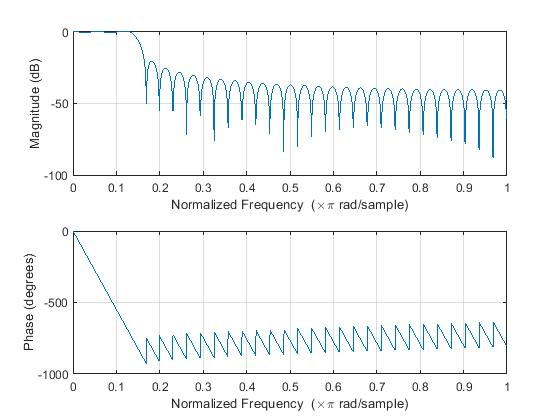

clear all; clc;


N=62;
Fc=0.15;

a= (N)/2;    
if mod(N,2)==0 
    a= (N-1)/2;
end

hn = @(m) sin( pi*Fc*(m-a) )./( pi*(m-a) );
%h = [Fc/pi hn(1:N-1)];


h = hn(0:N-1);

w = @(m) 1;
%w = @(m) 1/2*[1-cos(2*pi*m/(N-1))];
%h = 1/N*[hn(0:N-1)].*w(0:N-1);


freqz(h.*w(0:N-1), 1, 1024)